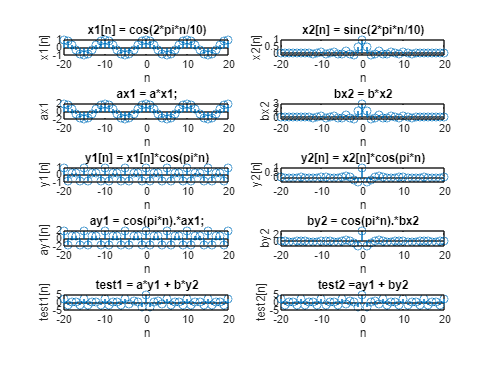

% Given system defined by the equation
% y[n] = cos(pi*n)*x[n]
% x1[n] = cos(2*pi*n/10)
% x2[n] = sinc(2*pi*n/10)

% Define the range of n
n = -20:20;

a = 2; % Choose arbitrary value for a
b = 3; % Choose arbitrary value for b

% Define the input signals
x1 = cos(2*pi*n/10);
x2 = sinc(2*pi*n/10);

% Define the output signals
y1 = x1.*cos(pi*n);
y2 = x2.*cos(pi*n);

%defining ax1 and ax2
ax1 = a*x1;
bx2 = b*x2;

ay1 = cos(pi*n).*ax1;
by2 = cos(pi*n).*bx2;

% Determine whether the system is linear or not

test1 = a*y1 + b*y2;
test2 = ay1 + by2;

% Plot the input signals
subplot(5, 2, 1);
stem(n, x1);
title('x1[n] = cos(2*pi*n/10)');
xlabel('n');
ylabel('x1[n]');

subplot(5, 2, 2);
stem(n, x2);
title('x2[n] = sinc(2*pi*n/10)');
xlabel('n');
ylabel('x2[n]');

% Plot the Multiplied input signals
subplot(5, 2, 3);
stem(n, ax1);
title('ax1 = a*x1;');
xlabel('n');
ylabel('ax1');

subplot(5, 2, 4);
stem(n, bx2);
title('bx2 = b*x2');
xlabel('n');
ylabel('bx2');

% Plot the output signals
subplot(5, 2, 5);
stem(n, y1);
title('y1[n] = x1[n]*cos(pi*n)');
xlabel('n');
ylabel('y1[n]');

subplot(5, 2, 6);
stem(n, y2);
title('y2[n] = x2[n]*cos(pi*n)');
xlabel('n');
ylabel('y2[n]');

% Plot the output signals
subplot(5, 2, 7);
stem(n, ay1);
title('ay1 = cos(pi*n).*ax1;');
xlabel('n');
ylabel('ay1[n] ');

subplot(5, 2, 8);
stem(n, by2);
title('by2 = cos(pi*n).*bx2');
xlabel('n');
ylabel('by2');


subplot(5,2,9)
stem(n,test1)
title('test1 = a*y1 + b*y2');
xlabel('n');
ylabel('test1[n]');

subplot(5,2,10)
stem(n,test2)
title('test2 =ay1 + by2');
xlabel('n');
ylabel('test2[n]');


if isequal(test1, test2)
    disp('The system is linear');
else
    disp('The system is not linear');
end

The system is linear
